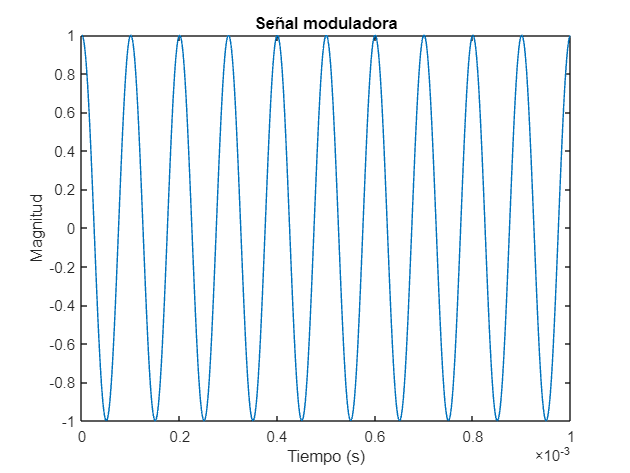

%  ---------- Simulación de la Transmisón y Recepción por AM (Exponencial Compleja) -----------------------

% Paso 1 - Generar el tono puro a transmitir

% Frecuencia de muestreo del transmisor (1 MHz)
% Frecuencia de la portadora (200 kHz)
% Índice de modulación (entre 0 y 1)
fs_tx = 1e6; 
f_c = 200e3; 
indice_modulacion = 1; 

% Frecuencia del tono puro (10 kHz)
% Duración del tono en segundos
f_m = 10e3;  
duracion = 0.001; 

% Vector de tiempo
t_tx = (0 : 1/fs_tx : duracion - 1/fs_tx); 

% Generar el tono puro (señal moduladora). Está normalizado, sino, sería
% necesario devidir entre su máximo.
moduladora = cos(2 * pi * f_m * t_tx);

% Figura 1: Señal Moduladora
figure
plot(t_tx, moduladora)
xlabel('Tiempo (s)');
ylabel('Magnitud');
title('Señal moduladora');

% sound(moduladora, 44100);

% Paso 2 - Simulación de la transmisión AM

% Señal portadora con exponencial compleja
portadora = exp(2 * pi * f_c * 1i * t_tx);

% Señal modulada en AM: (1 + m(t)) * portadora_exponencial_compleja
am_modulada = (1 + indice_modulacion * moduladora) .* portadora;
am_modulada_norm = am_modulada/max(am_modulada);

% Figrua 2: Señal modulada (Representación Temporal)
figure
plot(t_tx, am_modulada_norm);

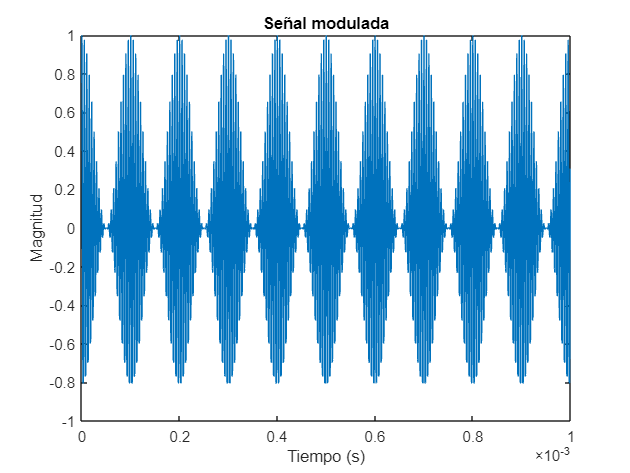

xlabel('Tiempo (s)');
ylabel('Magnitud');
title('Señal modulada');

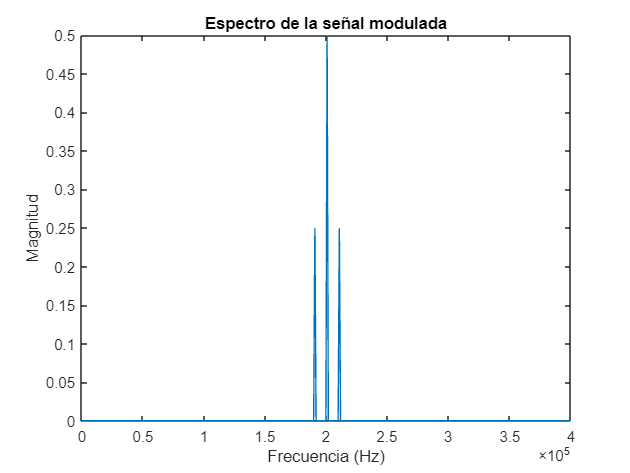


% Figrua 3: Señal modulada (Representación en frecuencia)
fft_modulada_norm = fftshift(abs(fft(am_modulada_norm, length(am_modulada_norm)))/length(am_modulada_norm)); 
fft_axis_modulada_norm = linspace(-fs_tx/2, fs_tx/2, length(am_modulada_norm));
figure 
plot(fft_axis_modulada_norm, abs(fft_modulada_norm))
xlim([0e5, 4e5])
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
title('Espectro de la señal modulada');

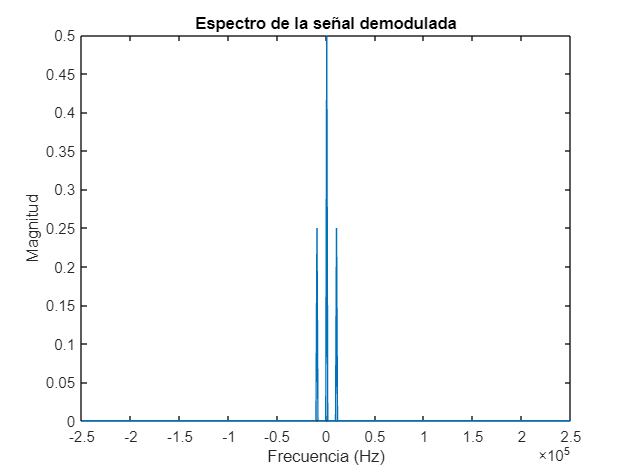

% Paso 3 - Procesado de la recepción AM

% Demodular la señal
portadora_recepcion =  exp(2 * pi * -f_c * i * t_tx);
signal_recibida = am_modulada_norm .* portadora_recepcion;

% Figura 4: Espectro de la señal demodulada
fft_signal_received = fftshift(abs(fft(signal_recibida, length(signal_recibida)))/length(signal_recibida)); 
fft_axis_signal_received = linspace(-fs_tx/2, fs_tx/2, length(signal_recibida));

figure
plot(fft_axis_signal_received, abs(fft_signal_received))
xlim([-2.5e5, 2.5e5])
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
title('Espectro de la señal demodulada');

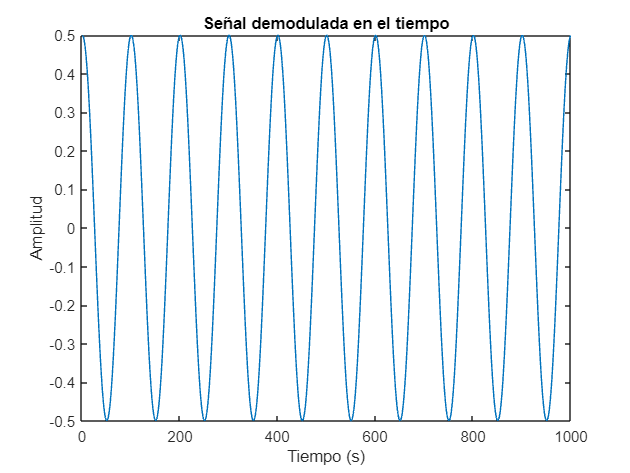

% Obtener la envolvente de la señal
envolvente = abs(signal_recibida);

% Se emplea un condensasdor, ya que no es necesario un filtrado por la modulación con la exponencial compleja. 
% Eliminar la componente continua
signal_demodulada = envolvente - mean(envolvente); 

% Figura 5: Señal recibida (Dominio Temporal)
figure;
plot(signal_demodulada);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Señal demodulada en el tiempo');

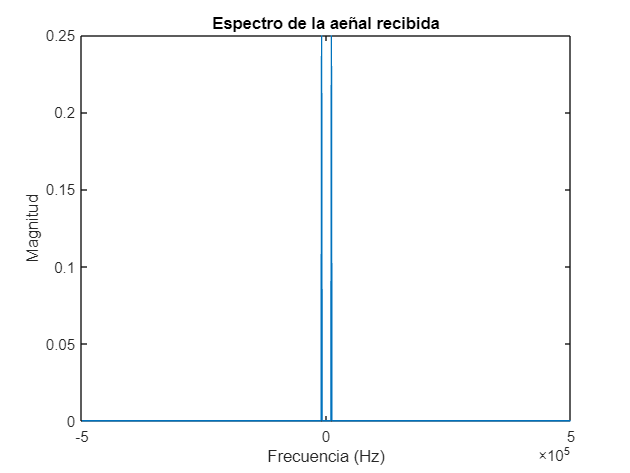

% Figura 6: Señal Recibida (Dominio de la frecuencia)
fft_datos_demodulada = fftshift(abs(fft(signal_demodulada, length(signal_demodulada))) / length(signal_demodulada));
fft_axis_demodulada = linspace(-fs_tx/2, fs_tx/2, length(signal_demodulada));

figure;
plot(fft_axis_demodulada, abs(fft_datos_demodulada));
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
title('Espectro de la aeñal recibida');